% Predefined variables
% f = @(t) A*exp(-a*t).*sin(omega_0*t); 
A = 444.128;
a = 50*sqrt(2)*pi;
omega_0 = a;

% x_n = [ones(1, rect_N) zeros(1, N-rect_N)]
rect_N = 10;

% h_n = [ones(1, rect_n) zeros(1, N-rect_n)]
rect_n = 10;

% EXPERIMENT RECIPE HERE

% Choose s1 for the first time, s2 for the second time and whether_pass to finish exp2-a
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Choose s2 for the first time, s1 for the second time and whether_pass free to finish exp2-b1
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Change do_exp_2_b2 =1(or make rect_N = 5)and then:
% hoose s2 for the first time, s1 for the second time and whether_pass for free to finish exp2-b2
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Change do_exp_3 =1, do_conv_test = 1, and then:
% Choose d for the first time, sampling frenquency = 1,
% s1 for the second time and whether_pass free to finish exp3
do_exp_2_b2 = 0; % 0 for common time
do_exp_3 = 1; % 0 for common time
do_conv_test = 1; % 1 for PREFORMANCE common

if do_exp_2_b2
    rect_N = 5;
end

if do_exp_3
    A = 1;
    a = 0.4;
    omega_0 = 2.0734
end

omega_0 = 2.0734

N = input('Determine the sequence length of x_n(The INPUT)(ENTER for 50)', 's');

if N == ""
    N = 50; % Count
else
    N = str2double(N)
end


choice = input(['DECIDE the sequence type' ...
    '("d" for "default function", ' ...
    'while "s1" for default sequence1 and' ...
    ' "s2" for default sequence2)' ...
    ' and"c" for custom function input'], 's');

f = 0;
switch choice
    case "d"        
        f = @(t) A*exp(-a*t).*sin(omega_0*t);
        disp(class(f))
    case "s1"
        x_n = [1 zeros(1, N-1)];
    case "s2"
        x_n = [ones(1, rect_N) zeros(1, N-rect_N)];
    case "c"
        f = input("Input the function handle to be sampled");
end

function_handle



if class(f) == "function_handle"
    fs = input('Decide the sampling frenquency(ENTER for 1000)', 's');
    if fs == ""
        fs = 1000; % Sampling frenquency
    else
        fs = str2double(fs)
    end
    
    T = 1/fs; % Sampling Period
    x_n = f((0:N-1)*T);
end

fs = 1

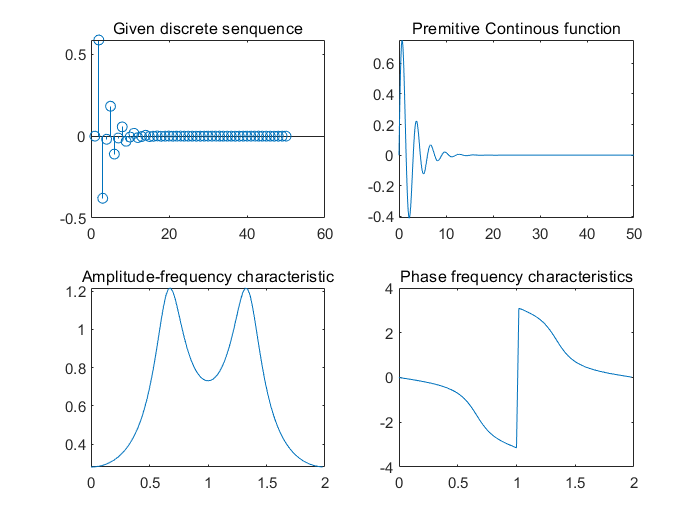

    

M = input('Decide the DTFT sampling dots(ENTER for 100)', 's');
if M == ""
    M = 100;
else
    M = str2double(M);
end

[mag_X, ang_X, w] = dft(x_n, M);

figure
subplot(2, 2, 1)
stem(x_n)
title("Given discrete senquence")

if class(f) == "function_handle"
    subplot(2, 2, 2)
    fplot(f, [0 N*T]);
    title("Premitive Continous function")
end

subplot(2, 2, 3)
plot(w/pi, mag_X)
title("Amplitude-frequency characteristic")

subplot(2, 2, 4)
plot(w/pi, ang_X)
title("Phase frequency characteristics")

N = input('Determine the sequence length of h_n(ENTER for 20)', 's');

if N == ""
    N = 20; % Count
else
    N = str2double(N)
end

choice = input(['DECIDE the h_n' ...
    '"s1" for default sequence1 and' ...
    '"s2" for default sequence2'], 's')

choice = 's1'

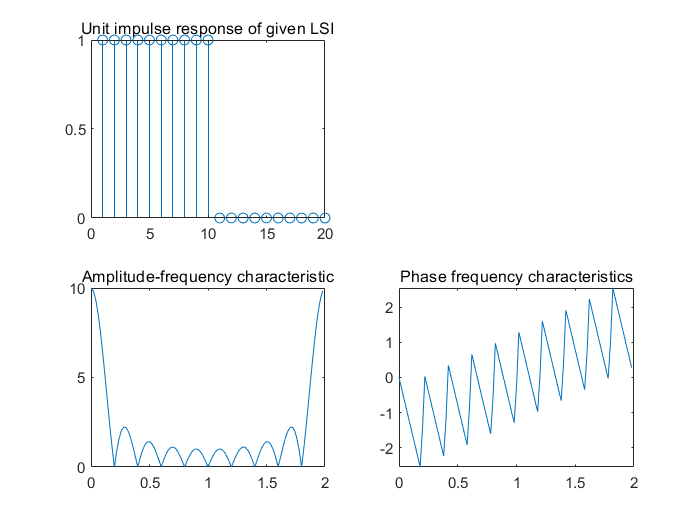


switch choice
    case "s2"
        h_n = [[1 2.5 2.5 1], zeros(1, N-4)];
    case "s1"
        h_n = [ones(1, rect_n) zeros(1, N-rect_n)];
end

M = input('Decide the DTFT sampling dots(ENTER for 100)', 's');
if M == ""
    M = 100;
else
    M = str2double(M);
end

[mag_H, ang_H, w] = dft(h_n, M);

figure
subplot(2, 2, 1)
stem(h_n)
title("Unit impulse response of given LSI")

subplot(2, 2, 3)
plot(w/pi, mag_H)
title("Amplitude-frequency characteristic")

subplot(2, 2, 4)
plot(w/pi, ang_H)
title("Phase frequency characteristics")

system_pass = input('Whether pass(ENTER for PASS THROUGH)', 's')


system_pass =

  空的 0×0 char 数组



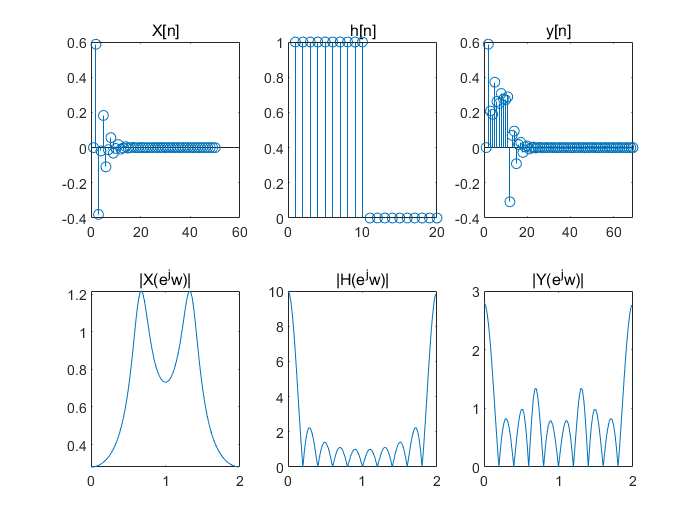

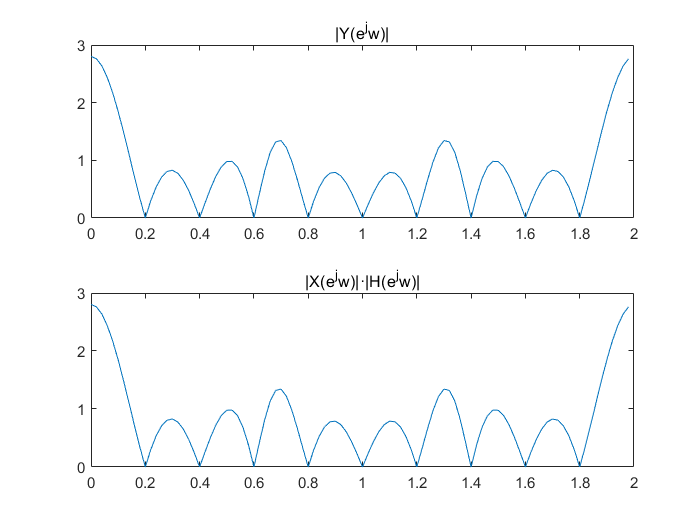


if system_pass == ""
    M = 100;
    y_n = conv(x_n, h_n);
    [mag_Y, ~, ~] = dft(y_n, M);
    
    [mag_X, ~, ~] = dft(x_n, M);
    
    [mag_H, ~, w] = dft(h_n, M);
    
    
    figure
    subplot(2, 3, 1)
    stem(x_n)
    title('X[n]')
    
    subplot(2, 3, 2)
    stem(h_n)
    title('h[n]')
    
    subplot(2, 3, 3)
    stem(y_n)
    title('y[n]')
    
    subplot(2, 3, 4)
    plot(w/pi, mag_X)
    title('|X(e^jw)|')
    
    subplot(2, 3, 5)
    plot(w/pi, mag_H)
    title('|H(e^jw)|')
    
    subplot(2, 3, 6)
    plot(w/pi, mag_Y)
    title('|Y(e^jw)|')
    
    if do_conv_test
        figure
        subplot(2, 1, 1)
        plot(w/pi, mag_Y)
        title('|Y(e^jw)|')
        
        subplot(2, 1, 2)
        plot(w/pi, mag_X .* mag_H)
        title('|X(e^jw)|·|H(e^jw)|')
        
    end
      
end

function [mag_X, ang_X, w] = dft(x, M)
    omega_k = 2*pi/M;
    k = 0:M-1;
    w = omega_k *k;
    X_w = x * (exp(-1j*omega_k)).^((0:length(x)-1)'*k);
    mag_X = abs(X_w);
    ang_X = angle(X_w);
end